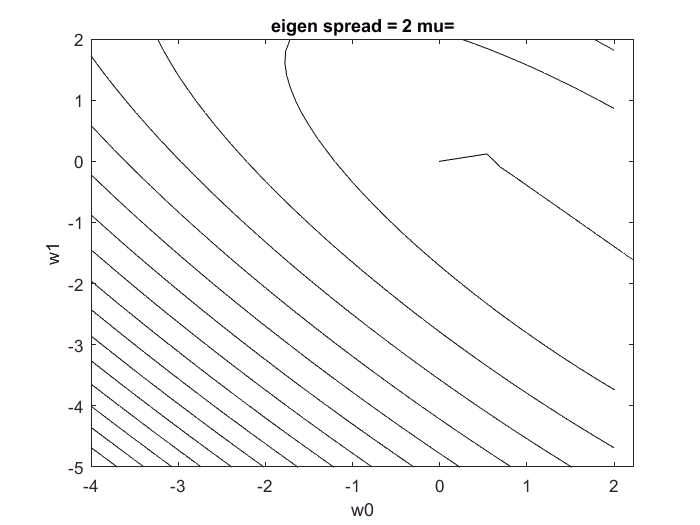

%Steepest decent method when eigen spread is 2
clc;
clear all;
close all;
% es = 2;%eigen spread
a = 9/11;%input("enter alpha values: ");
%R=[a 1;1 a];
%p = [0.9 0.2];
m=0.3;
w0(1) = 0; w1(1) = 0;
for k = 1:150
 w0(k+1) = w0(k)-2*m*(w0(k)+ a*w1(k))+2*m*(0.9);
 w1(k+1) = w1(k)-2*m*(a*w0(k)+ w1(k))+2*m*(0.2);
end
x=-4:0.2:2; y = -5:0.2:2;
[X,Y]=meshgrid(x,y);
J=1+X.^2+ Y.^2 + 2*a.*X.*Y-2*(0.9).*X-2*(0.2).*Y;
contour(X,Y,J,15,'k');
 k=1:150;
 hold on; plot(w0,w1,'k');
 title('eigen spread = 2 mu');
 xlabel('w0');
 ylabel('w1');

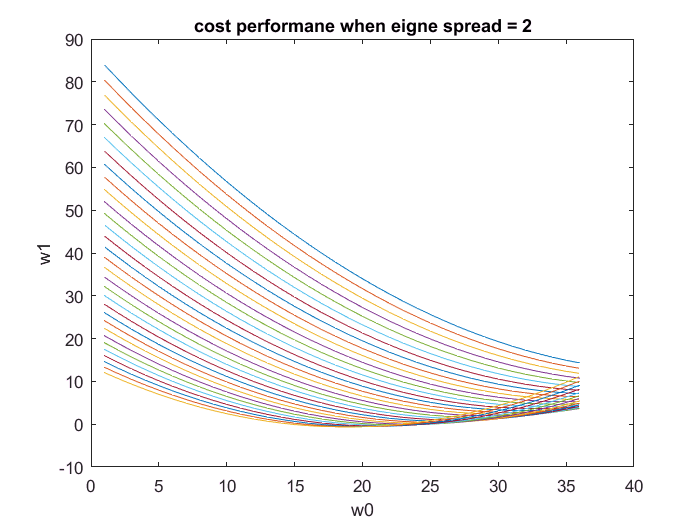

 figure(2)
 plot(J)
 title('cost performane when eigne spread = 2');
 xlabel('w0');
 ylabel('w1');